# Transfer Functions

## Logistic (weight)

syms x w
f(x, w) = 1 / (1 + exp(-w * x))

$$f(x, w) = \frac{1}{{\mathrm{e}}^{-w\,x}+1}$$

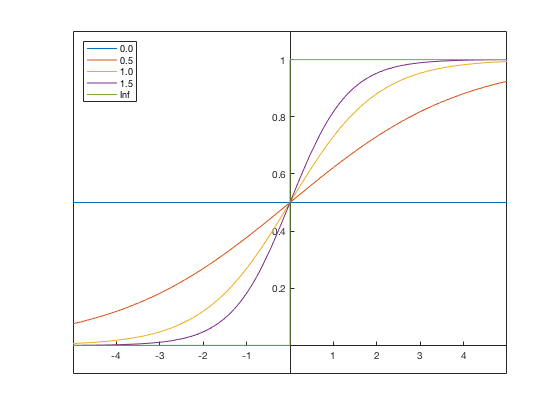

fplot(f(x, 0.0));
hold on
fplot(f(x, 0.5));
fplot(f(x, 1.0));
fplot(f(x, 1.5));
fplot(f(x, Inf));
hold off
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
ylim([-0.1, 1.1]);
legend('0.0', '0.5', '1.0', '1.5', 'Inf', 'Location', 'northwest');

## Logistic (bias)

syms x b
f(x, b) = 1 / (1 + exp(-(x - b)));

$$f(x, b) = \frac{1}{{\mathrm{e}}^{b-x}+1}$$

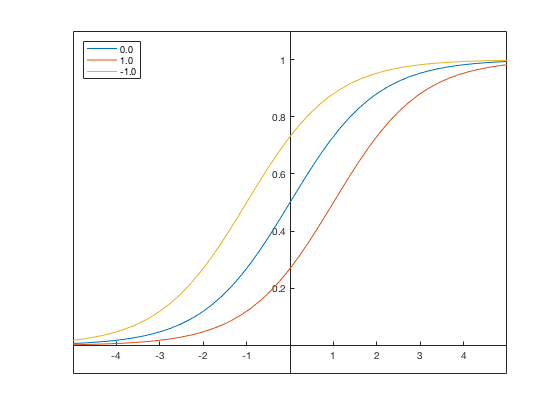

fplot(f(x, 0.0));
hold on
fplot(f(x, 1.0))
fplot(f(x, -1.0))
hold off
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
ylim([-0.1, 1.1]);
legend('0.0', '1.0', '-1.0', 'Location', 'northwest');

## Logistic (L, w, b)

syms x L w b
f(x, L, w, b) = L / (1 + exp(-w * (x - b)))

$$f(x, L, w, b) = \frac{L}{{\mathrm{e}}^{w\,\left(b-x\right)}+1}$$

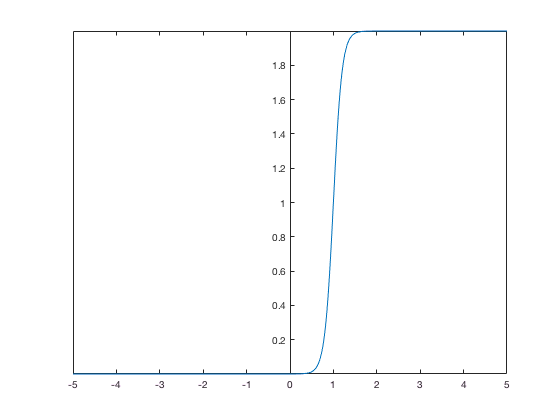

fplot(f(x, 1.0, 2.0, 1.0));
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')

## Tangent hyperbolic = 2 * Logistic(2, 0) - 1

syms x w b
f(x, w, b) = 1 / (1 + exp(-w * (x - b)))

$$f(x, w, b) = \frac{1}{{\mathrm{e}}^{w\,\left(b-x\right)}+1}$$

g(x) = 2 * f(x, 2, 0) - 1

$$g(x) = \frac{2}{{\mathrm{e}}^{-2\,x}+1}-1$$

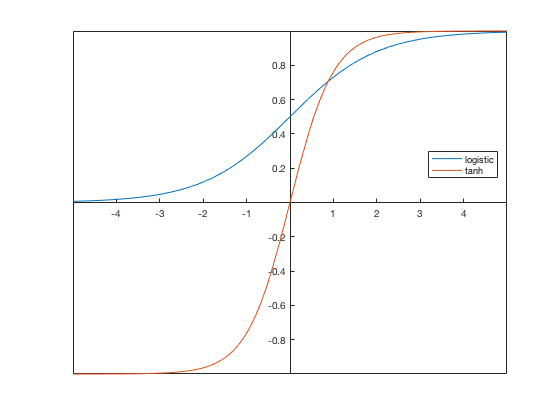

fplot(f(x, 1.0, 0.0));
hold on
fplot(g(x));
hold off
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
legend('logistic', 'tanh', 'Location', 'best')